%**************************************************************************
% AUTHOR: Brayan Espinoza
% DATE: 28/10/2024
% DESCRIPTION: 
% This program implements a grey estimation algorithm to obtain the 
% parameters required for simulating the "EC Flat 45" brushless motor 
% with the "ESCBLHeli S" controller.
%
% *************************************************************************

%%% Nominal motor values - These constants represent the physical and electrical 
%%% characteristics of the brushless motor.
% kt: Torque constant (Nm/A) - Relates the motor current to the torque produced.
motor.kt = 0.000872234;  % Torque constant
% J: Inertia (kg*m^2) - Represents the rotational inertia of the motor rotor.
motor.J  = 2.55E-5;      % Rotational inertia
% b: Damping coefficient (Nms/rad) - Represents the frictional losses in the motor.
motor.b  = 1.00023E-05;  % Damping coefficient
% c: Motor constant related to back EMF (V/(rad/s)) - Affects the voltage generated 
% when the motor is spinning.
motor.c  = 0.000435786;   % Back EMF constant
% L: Inductance (H) - Represents the inductance of the motor windings.
motor.L  = 0.000176564;   % Inductance
% R: Resistance (Ohm) - Represents the electrical resistance of the motor windings.
motor.R  = 1.23424;       % Resistance
% Ke: Electromotive force constant (V/(rad/s)) - The constant that relates the 
% angular velocity to the back EMF generated by the motor.
motor.Ke = 0.00966471;    % Back EMF constant

%%% Convert the motor structure to an array for further processing.
% The 'struct2cell' function converts the structure 'motor' into a cell array, 
% and 'cell2mat' converts that cell array into a numerical matrix.
initial = cell2mat(struct2cell(motor));  % Initialize array with motor parameters

% Note: The resulting 'initial' variable will be a 1x6 array containing the 
% parameters: [kt, J, b, c, L, R, Ke].


%%% 1. Read data measured from the experiment
nombre_archivo = 'RPMdata1.csv';  % Specify the name of the CSV file containing experimental data.

% dt: Set sample time
dt = 1;  % Desired sample time in seconds (can be adjusted as needed).

%%% Read data from the CSV file
datos = readtable(nombre_archivo);  % Load the data from the CSV file into a table.

%%% Add voltage equivalents
% Calculate the voltage based on the Input_PWM values.
% The formula assumes a PWM input range from 1100 to 1900 (for a total range of 800),
% mapping it to a voltage range of -12V to 12V.
datos.voltage = ((datos.Input_PWM - 1100) * (24 / 800)) - 12;  % Convert PWM to voltage.

%%% Interpolate data to set the desired sample time
% Use the 'setSampleTime' function to obtain uniform sampling for RPM, Current, and Voltage.
[newDatos.time, newDatos.RPM] = setSampleTime(datos.time_s, datos.Velocidad_rpm, dt);
[~, newDatos.current] = setSampleTime(datos.time_s, datos.Current_A, dt);
[~, newDatos.voltage] = setSampleTime(datos.time_s, datos.voltage, dt);

%%% Update signs
% Adjust the RPM and current values based on the sign of the voltage.
% This accounts for the direction of the motor and any offset in current readings.
newDatos.RPM = sign(newDatos.voltage) .* newDatos.RPM;  % Update RPM based on voltage sign.
newDatos.current = sign(newDatos.voltage) .* (newDatos.current - 0.025);  % Adjust current readings with an offset.

% 2. Represent the estimation data as an iddata object.
% Create the output vector 'y' by combining the angular rate (RPM converted to rad/s)
% and the current data into a two-column matrix. The conversion from RPM to rad/s 
% is done by multiplying by pi/30 (since 1 RPM = pi/30 rad/s).
y = [newDatos.RPM * pi / 30; newDatos.current]';  % Transpose to create a matrix where each row represents a time step.

% Create the input vector 'u' using the voltage data, which will be the input to the system.
u = newDatos.voltage';  % Transpose to match the required format.

% Construct the iddata object 'z' which contains the input-output data for system identification.
% The 'iddata' object encapsulates the input and output data along with the sample time.
z = iddata(y, u, dt, 'Name', 'DC-motor');

%% 
% 3. Specify input and output signal names, start time, and time units.
% Set the name and unit for the input signal (voltage).
z.InputName = 'Voltage';          % Name of the input signal.
z.InputUnit = 'V';                % Unit of the input signal (Volts).

% Set the names and units for the output signals (angular rate and motor current).
z.OutputName = {'Angular rate', 'Motor current'};  % Names of the output signals.
z.OutputUnit = {'rad/s', 'A'};                      % Units of the output signals (radians per second and Amperes).

% Specify the start time for the data collection.
z.Tstart = 0;                      % Start time of the data collection.

% Set the time unit for the iddata object.
z.TimeUnit = 's';                  % Time unit (seconds).

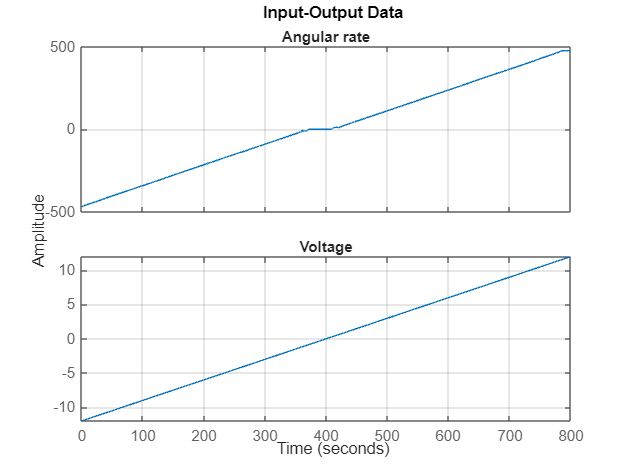

% 4. Plot the data.
% This section generates two separate plot windows to visualize the relationship 
% between the input (voltage) and the outputs (angular rate and motor current).

% Create a figure window for plotting the relationship between the current input 
% (voltage) and the angular rate output (RPM converted to rad/s).
figure('Name', [z.Name ': Current input -> Angular rate output']);
plot(z(:, 1, 1));  % Plot the first input-output pair: Voltage (input) -> Angular rate (output).
grid on;           % Enable grid on the plot for better readability.

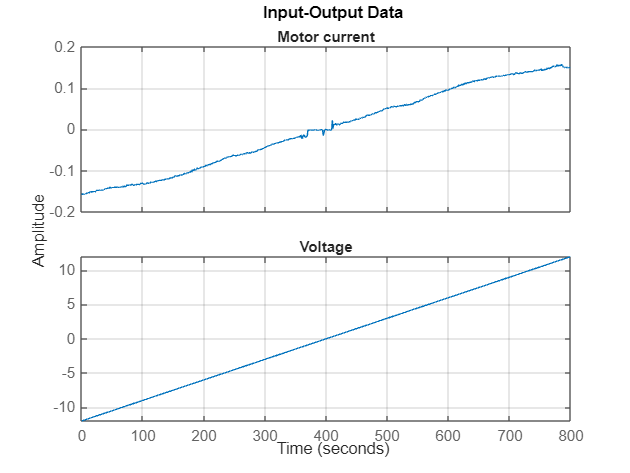


% Create another figure window for plotting the relationship between the voltage input 
% and the motor current output.
figure('Name', [z.Name ': Voltage input -> Motor current output']);
plot(z(:, 2, 1));  % Plot the second input-output pair: Voltage (input) -> Motor current (output).
grid on;           % Enable grid on the plot for better readability.

% 2. Represent the DC motor dynamics using an idnlgrey object.
% This code creates a nonlinear grey-box model for the DC motor dynamics 
% using the specified model structure, initial parameters, and state conditions.

% Specify the name of the file that contains the model structure.
FileName = 'BrushelessModel';  % Name of the function file that defines the model.

% Specify the model orders:
% [ny nu nx] where:
% ny = number of outputs,
% nu = number of inputs,
% nx = number of states.
Order = [2 1 2];  % Here, we have 2 outputs, 1 input, and 2 states.

% Set initial parameters for the model.
% This should be a column vector containing the initial values of the model parameters.
Parameters = initial';  % Using previously defined 'initial' values for parameters.

% Define the initial states for the system:
% This vector represents the starting conditions for the state variables.
InitialStates = [-500; 0.15 - 0.025];  % Initial angular rate and current (adjusted for offset).

% Specify the time type for the system.
% Ts = 0 indicates a continuous-time system, while Ts > 0 would indicate a discrete-time system.
Ts = 0;  % Continuous-time system.

% Create the idnlgrey object representing the nonlinear grey-box model.
% This object encapsulates the model structure, orders, parameters, initial states, and time specification.
nlgr = idnlgrey(FileName, Order, Parameters, InitialStates, Ts, ...
                'Name', 'DC-motor');  % Assign a name to the model for identification.


% 3. Specify input and output names, and units.
set(nlgr, 'InputName', 'Voltage', 'InputUnit', 'V',               ...
          'OutputName', {'Angular rate', 'Motor current'}, ...
          'OutputUnit', {'rad/s', 'A'},                         ...
          'TimeUnit', 's');

% 4. Specify names and units of the initial states and parameters.
nlgr = setinit(nlgr, 'Name',  {'Angular rate', 'Motor current'});
nlgr = setinit(nlgr, 'Unit', {'rad/s', 'A'});
%nlgr = setpar(nlgr, 'Name', {'Torque constant' 'Rotor inertia' 'Constante de friccion viscosa' 'Inductancia' 'Resistencia' 'Constante contraelectromotriz' });
%nlgr = setpar(nlgr, 'Unit', {'N*m/A' 'kg*m^2' 'N*m*s' 'H' 'R' 'V/(Rad/s)' });

nlgr = setpar(nlgr, 'Name', {'Torque constant' 'Rotor inertia' 'Constante de friccion viscosa' 'Constante de friccion de Coulomb' 'Inductancia' 'Resistencia' 'Constante contraelectromotriz' });
nlgr = setpar(nlgr, 'Unit', {'N*m/A' 'kg*m^2' 'N*m*s' 'N*m*s' 'H' 'R' 'V/(Rad/s)' });

%nlgr = setpar(nlgr, 'Name', {'Torque constant' 'Rotor inertia' 'Constante de friccion viscosa' ...
%    'Constante de friccion de Coulomb' 'Inductancia' 'Resistencia' 'Constante contraelectromotriz' 'Starting Torque' ...
%    'Stribeck angular rate'});
%nlgr = setpar(nlgr, 'Unit', {'N*m/A' 'kg*m^2' 'N*m*s' 'N*m*s' 'H' 'R' 'V/(Rad/s)' 'N*m' 'rad/s'});


% 5. View the initial model.
%
% a. Get basic information about the model.
%
% The DC-motor has 2 (initial) states and 2 model parameters.
size(nlgr)

Nonlinear grey-box model with 2 outputs, 1 inputs, 2 states and 7 parameters (7 free).


% b. View the initial states and parameters.
% This section demonstrates how to access and modify the initial states and parameters 
% of the idnlgrey model object 'nlgr'. The initial states and parameters are structured arrays, 
% with fields specifying their properties.

% Access and modify the properties of the first parameter in the model.
nlgr.Parameters(1).Minimum = 0;  % Set the minimum value for the first parameter.
nlgr.Parameters(1)                % Display the properties of the first parameter.

ans = struct with fields:
       Name: 'Torque constant'
       Unit: 'N*m/A'
      Value: 8.7223e-04
    Minimum: 0
    Maximum: Inf
      Fixed: 0



% Access and modify the properties of the second parameter in the model.
nlgr.Parameters(2).Minimum = eps(0);  % Set the minimum value for the second parameter (smallest positive number).
nlgr.Parameters(2).Fixed = 1;         % Mark the second parameter as fixed (not subject to estimation).
nlgr.Parameters(2)                    % Display the properties of the second parameter.

ans = struct with fields:
       Name: 'Rotor inertia'
       Unit: 'kg*m^2'
      Value: 2.5500e-05
    Minimum: 4.9407e-324
    Maximum: Inf
      Fixed: 1



% Access and modify the properties of the third parameter in the model.
nlgr.Parameters(3).Minimum = 0;  % Set the minimum value for the third parameter.
nlgr.Parameters(3)                % Display the properties of the third parameter.

ans = struct with fields:
       Name: 'Constante de friccion viscosa'
       Unit: 'N*m*s'
      Value: 1.0002e-05
    Minimum: 0
    Maximum: Inf
      Fixed: 0



% Access and modify the properties of the fourth parameter in the model.
nlgr.Parameters(4).Minimum = 0;  % Set the minimum value for the fourth parameter.
nlgr.Parameters(4)                % Display the properties of the fourth parameter.

ans = struct with fields:
       Name: 'Constante de friccion de Coulomb'
       Unit: 'N*m*s'
      Value: 4.3579e-04
    Minimum: 0
    Maximum: Inf
      Fixed: 0



% Access and modify the properties of the fifth parameter in the model.
nlgr.Parameters(5).Minimum = eps(0);              % Set the minimum value for the fifth parameter (smallest positive number).
nlgr.Parameters(5).Maximum = 1.5E-3;               % Set the maximum value for the fifth parameter.
nlgr.Parameters(5).Fixed = 0;                       % Mark the fifth parameter as variable (subject to estimation).
nlgr.Parameters(5)                                  % Display the properties of the fifth parameter.

ans = struct with fields:
       Name: 'Inductancia'
       Unit: 'H'
      Value: 1.7656e-04
    Minimum: 4.9407e-324
    Maximum: 0.0015
      Fixed: 0



% Access and modify the properties of the sixth parameter in the model.
nlgr.Parameters(6).Minimum = 0;                     % Set the minimum value for the sixth parameter.
nlgr.Parameters(6).Maximum = 5;                     % Set the maximum value for the sixth parameter.
nlgr.Parameters(6).Fixed = 0;                       % Mark the sixth parameter as variable (subject to estimation).
nlgr.Parameters(6)                                  % Display the properties of the sixth parameter.

ans = struct with fields:
       Name: 'Resistencia'
       Unit: 'R'
      Value: 1.2342
    Minimum: 0
    Maximum: 5
      Fixed: 0



% Access and modify the properties of the seventh parameter in the model.
nlgr.Parameters(7).Minimum = eps;                   % Set the minimum value for the seventh parameter (smallest positive number).
nlgr.Parameters(7)                                  % Display the properties of the seventh parameter.

ans = struct with fields:
       Name: 'Constante contraelectromotriz'
       Unit: 'V/(Rad/s)'
      Value: 0.0097
    Minimum: 2.2204e-16
    Maximum: Inf
      Fixed: 0


% c. Retrieve information for all initial states or model parameters in one
% call.
% 
% For example, obtain information on initial states that are fixed (not
% estimated) and the minima of all model parameters.
getinit(nlgr, 'Fixed')

ans = 2×1 cell array
    {[1]}
    {[1]}


getpar(nlgr, 'Min')

ans = 7×1 cell array
    {[          0]}
    {[4.9407e-324]}
    {[          0]}
    {[          0]}
    {[4.9407e-324]}
    {[          0]}
    {[ 2.2204e-16]}


% d. Obtain basic information about the object:
nlgr

nlgr =

Continuous-time nonlinear grey-box model defined by 'BrushelessModel' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p7)
    y(t) = H(t, u(t), x(t), p1, ..., p7) + e(t)

 with 1 input(s), 2 state(s), 2 output(s), and 6 free parameter(s) (out of 7).

Name: DC-motor

Status:                                                         
Created by direct construction or transformation. Not estimated.

Model Properties


%%
% Use |get| to obtain more information about the model properties. The
% |idnlgrey| object shares many properties of parametric linear model
% objects.
get(nlgr)

             FileName: 'BrushelessModel'
                Order: [1×1 struct]
           Parameters: [7×1 struct]
        InitialStates: [2×1 struct]
         FileArgument: {}
    SimulationOptions: [1×1 struct]
         TimeVariable: 't'
        NoiseVariance: [2×2 double]
            InputName: {'Voltage'}
            InputUnit: {'V'}
           InputGroup: [1×1 struct]
           OutputName: {2×1 cell}
           OutputUnit: {2×1 cell}
          OutputGroup: [1×1 struct]
                Notes: [0×1 string]
             UserData: []
                 Name: 'DC-motor'
                   Ts: 0
             TimeUnit: 'seconds'
               Report: [1×1 idresults.nlgreyest]



%% Performance Evaluation of the Initial DC-Motor Model
%
% Before estimating the parameters |tau| and |k|, simulate the output of
% the system with the parameter guesses using the default differential
% equation solver (a Runge-Kutta 45 solver with adaptive step length
% adjustment). The simulation options are specified using the
% "SimulationOptions" model property.
%
% 1. Set the absolute and relative error tolerances to
% small values (|1e-6| and |1e-5|, respectively).
nlgr.SimulationOptions.AbsTol = 1e-6;
nlgr.SimulationOptions.RelTol = 1e-5;

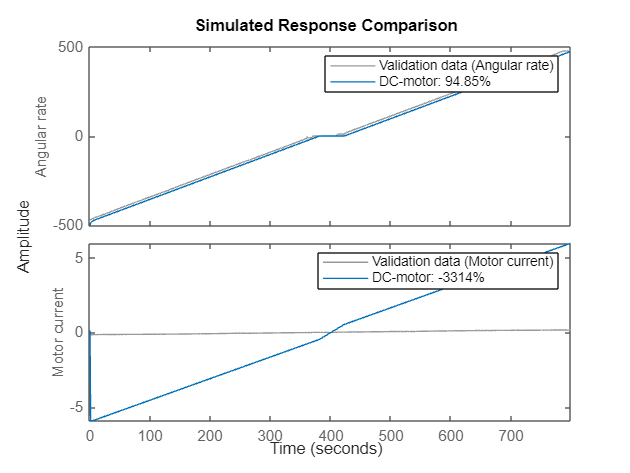

% 2. Compare the simulated output with the measured data.
%
% |compare| displays both measured and simulated outputs of one or more
% models, whereas |predict|, called with the same input arguments, displays
% the simulated outputs.
%
% The simulated and measured outputs are shown in a plot window.
compare(z, nlgr);

%% Parameter Estimation
% Estimate the parameters and initial states using |nlgreyest|, which is a
% prediction error minimization method for nonlinear grey box models. The
% estimation options, such as the choice of estimation progress display,
% are specified using the "nlgreyestOptions" option set.
nlgr = setinit(nlgr, 'Fixed', {false false}); % Estimate the initial states.
opt = nlgreyestOptions('Display', 'on');
nlgr = nlgreyest(z, nlgr, opt);

%% Performance Evaluation of the Estimated DC-Motor Model
% 1. Review the information about the estimation process.
%
% This information is stored in the |Report| property of the
% |idnlgrey| object. The property also contains information about how the
% model was estimated, such as solver and search method, data set, and why
% the estimation was terminated.
nlgr.Report
fprintf('\n\nThe search termination condition:\n')
nlgr.Report.Termination

%%
% 2. Evaluate the model quality by comparing simulated and measured
% outputs.
% 
% The fits are 98% and 84%, which indicate that the estimated model
% captures the dynamics of the DC motor well.
compare(z, nlgr);

%%
% *Figure 4:* Comparison between measured outputs and the simulated outputs
% of the estimated IDNLGREY DC-motor model.

%%
%
% 3. Compare the performance of the |idnlgrey| model with a second-order
% ARX model.
na = [2 2; 2 2];
nb = [2; 2];
nk = [1; 1];
dcarx = arx(z, [na nb nk]);
compare(z, nlgr, dcarx);

%%
% 4. Check the prediction errors.
%
% The prediction errors obtained are small and are centered around zero
% (non-biased).
pe(z, nlgr);